# Plotting Graphs in Matlab

In this script we demonstrate basic graphing with Matlab

clear %Clearing memory
close all

## Example 1: Plotting the graph of quadratic function

One way to plot a 2-dimensional graph of a function is by creating grid of points, and using the `plot` function.

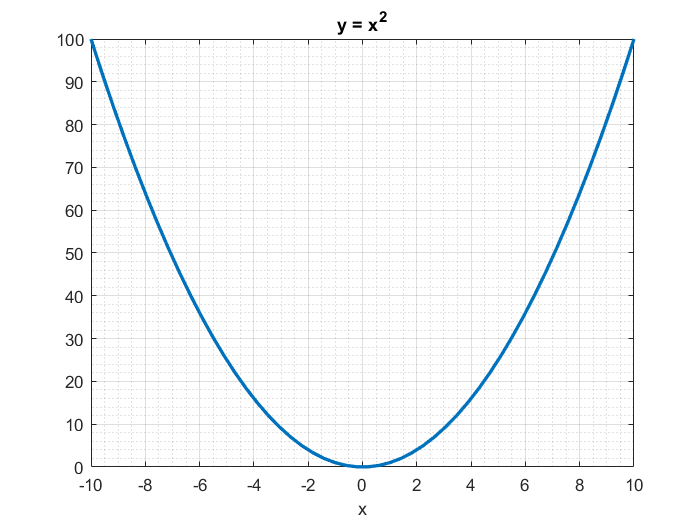

x = linspace(-10,10,50)'; %50 evenly spaced points in [-10, 10] interval
y = x.^2; %The .^ is element-wise square, i.e. each element is squared
plot(x,y,'LineWidth',2)
title('y = x^2')
xlabel('x')
grid on
grid minor

Another way to draw the same function is by using the `fplot` function from the **symbolic toolbox**. 

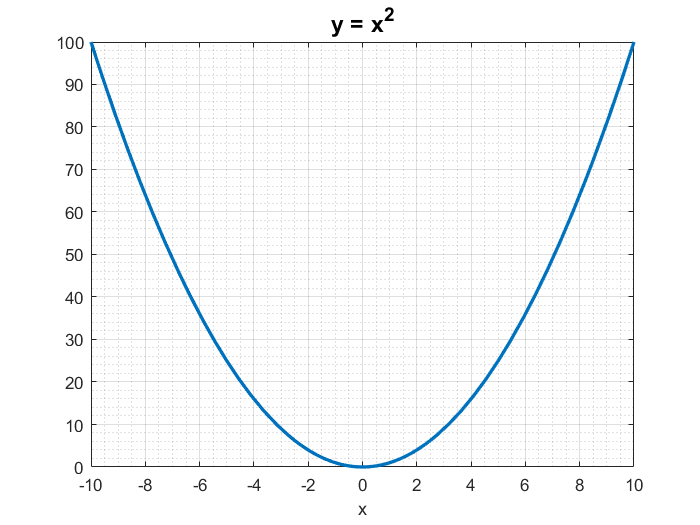

syms x %Declaring symbolic variable
f(x) = x^2; %Declaring symbolic function
fplot(f(x), [-10,10], 'LineWidth',2)
title('y = x^2', 'FontSize',14) %Notice how we changed the font size
xlabel('x')
grid on
grid minor

## Example 2: Plotting several graphs on one diagram 

Using grid and plot function.

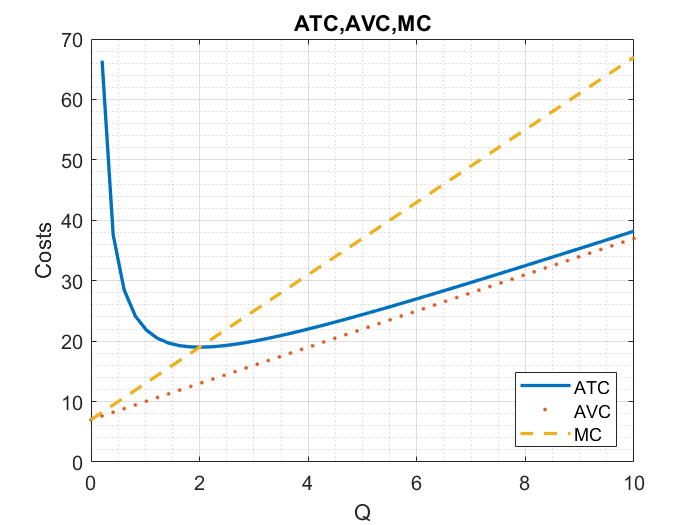

Q = linspace(0,10,50)'; %50 evenly spaced points in [0, 10] interval
ATC = 3*Q + 7 + 12./Q; %The ./ is element-wise division
AVC = 3*Q + 7;
MC  = 6*Q + 7;
plot(Q,ATC,Q,AVC,'.',Q,MC,'--','LineWidth',2)
set(gca,'FontSize',12); %Notice how we changed the font size of axes
title('ATC,AVC,MC', 'FontSize',14)
xlabel('Q')
ylabel('Costs')
legend('ATC','AVC','MC', 'Location', 'best')
grid on
grid minor

We can achieve the same by using the using the `fplot` function from the **symbolic toolbox**. 

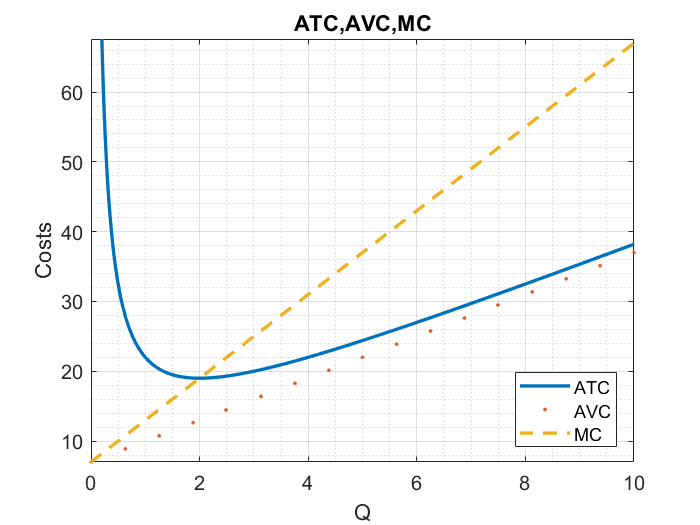

syms Q %Declaring symbolic variable
clear ATC AVC MC %Clearing previously defined objects
TC(Q) = 3*Q^2 + 7*Q + 12; %Declaring symbolic function (Total Cost)
VC(Q) = 3*Q^2 + 7*Q; %Declaring symbolic function (Variable Cost)
ATC(Q) = TC(Q)/Q; %Declaring symbolic function (Average Total Cost)
AVC(Q) = VC(Q)/Q; %Declaring symbolic function (Average Variable Cost)
MC  = diff(TC(Q),Q); %Declaring symbolic function (Marginal Cost)
fplot(ATC,[0.2,10], 'LineWidth',2)
hold on %Adding more plots
fplot(AVC,[0,10], '.','LineWidth',2)
fplot(MC, [0,10], '--','LineWidth',2)
set(gca,'FontSize',12); %Notice how we changed the font size of axes
title('ATC,AVC,MC', 'FontSize',14)
xlabel('Q')
ylabel('Costs')
legend('ATC','AVC','MC', 'Location', 'best')
grid on
grid minor
hold off %Turning off the addition of more plots

## Example 3: Plotting 3-dimentional graphs

As with 2-dimensional graphs, one way to go is to plot grid points.

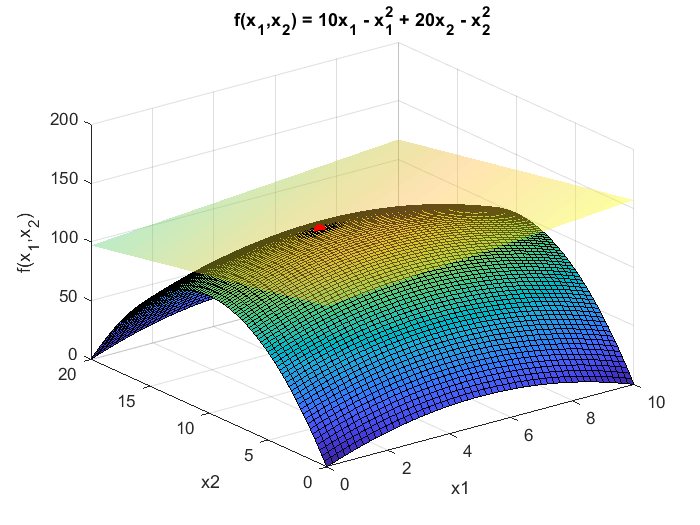

x1 = linspace(0,10,51)'; %100 equally spaced points in [0,10] interval
x2 = linspace(0,20,101)'; %100 equally spaced points in [0,20] interval
[X1,X2] = meshgrid(x1,x2);
y = 10*X1 - X1.^2 + 20*X2 - X2.^2;
surf(X1,X2,y)
title('f(x_1,x_2) = 10x_1 - x_1^2 + 20x_2 - x_2^2')
xlabel('x1')
ylabel('x2')
zlabel('f(x_1,x_2)')
% Tangent plane at x1 = 4, x2 = 11
hold on
plot3(4,11,123,'.r','MarkerSize',25) %Point of tangency
z = 137 + 2*X1 - 2*X2; %Tangent plane
surf(X1,X2,z, 'EdgeColor','none','FaceAlpha',0.4);
hold off

Alternatively, we can use the `fsurf` function from the **symbolic toolbox**. 

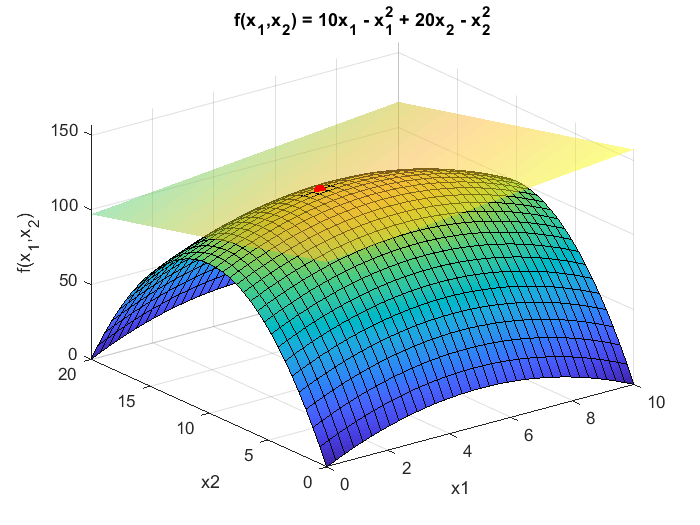

syms x1 x2 %Declaring symbolic variables
f(x1,x2) = 10*x1 - x1^2 + 20*x2 - x2^2; %Declaring symbolic function
% rotate3d on %Use this command if you want to rotate the figure
fsurf(f(x1,x2),[0 10 0 20] )
title('f(x_1,x_2) = 10x_1 - x_1^2 + 20x_2 - x_2^2')
xlabel('x1')
ylabel('x2')
zlabel('f(x_1,x_2)')
% Tangent plane at x1 = 4, x2 = 11
hold on
plot3(4,11,123,'.r','MarkerSize',25) %Point of tangency
d(x1,x2) = 137 + 2*x1 - 2*x2; %Tangent plane
fsurf(d(x1,x2), [0 10 0 20],'EdgeColor','none','FaceAlpha',0.5);
hold off

## Example 4: Shaded areas under the graph

We show how to shade the areas under the normal pdf.

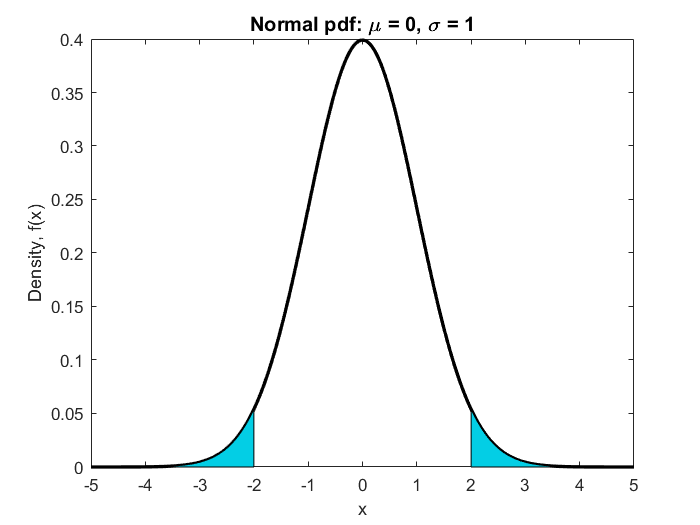

x = linspace(-5,5,1001)';
mu = 0; sigma = 1;
y = npdf(x,mu,sigma);
plot(x,y,'k','LineWidth',2);
hold on
shade = x>=2;
h = area(x(shade),y(shade));
h(1).FaceColor = [3 206 229] ./ 255;
shade = x<=-2;
h = area(x(shade),y(shade));
h(1).FaceColor = [3 206 229] ./ 255;
title(['Normal pdf: ','\mu = ',num2str(mu),', \sigma = ',num2str(sigma)],...
    'FontSize',12)
xlabel('x')
ylabel('Density, f(x)')